# Example with numeric values

This example shows how to use the symbolic beam solver with a numeric task on hand.

*Task:*

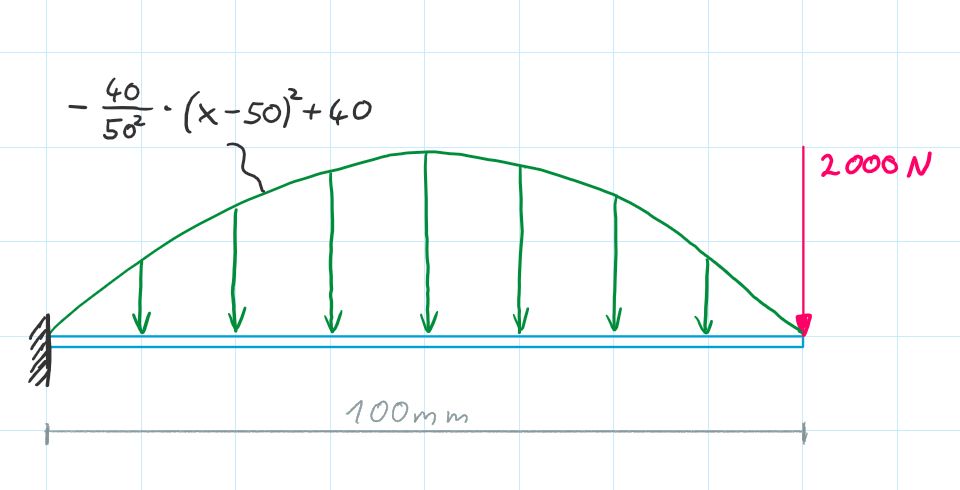

clear 'all'  % clear all variables ('all' also clears assumptions)

#### create a beam

mybeam = beam(100);  % define a beam with given length

#### define external influences

% Bearings
Bearing_A = bearing(0, 3, 'A');

% Pointloads/Forces
F1 = pointload(100, 2000);

% Lineload
syms x  % define x first
L1 = lineload(0, 100, -40/50^2*(x-50)^2 + 40);

#### add influeces to beam

mybeam.bearings = Bearing_A;
mybeam.pointloads = F1;
mybeam.torques = [];  % this line is not nessescary since no torque is added
mybeam.lineloads = L1;

#### check beam-setup

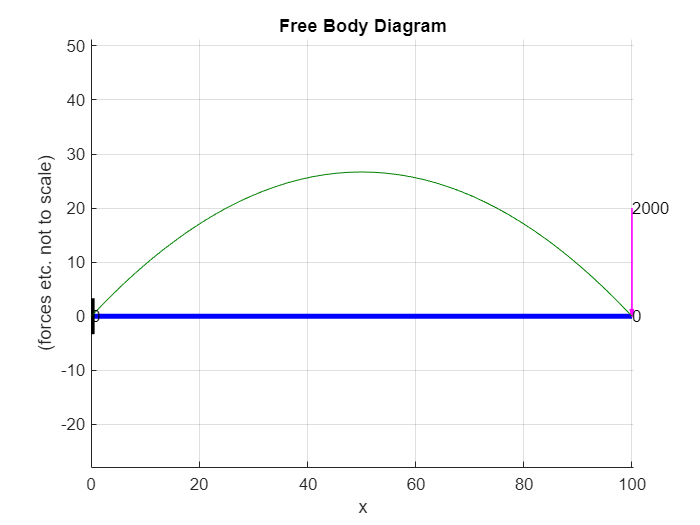

figure(1); clf; hold on; grid on; axis equal;
mybeam.plot_beam()

#### solve beam

Especially when using symbolic variables this process may take a while

mybeam.fullsolve()  % this solves the beam

#### visualize shear force and bending moment

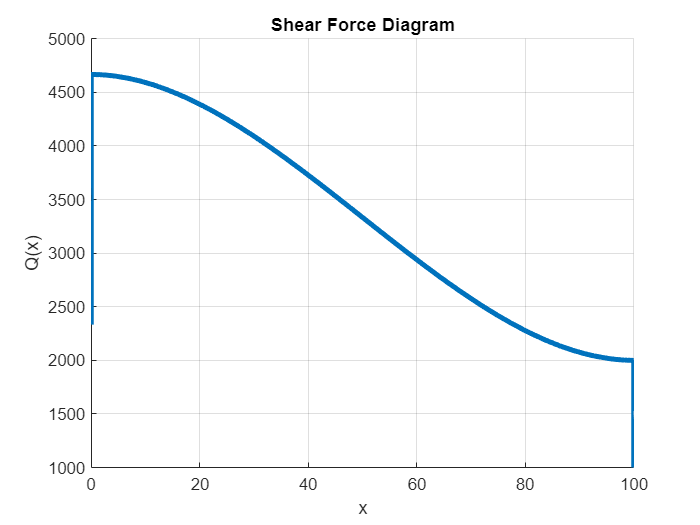

figure(2); clf; hold on; grid on;
mybeam.plot_Q()

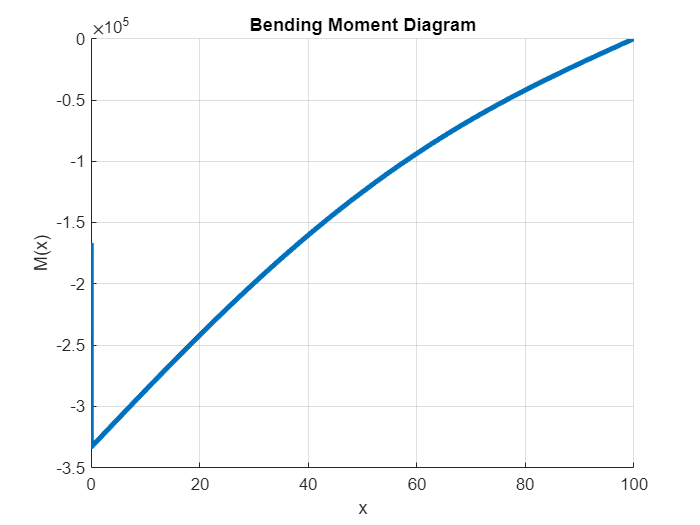


figure(3); clf; hold on; grid on;
mybeam.plot_M()

#### show formula for shear forces and bending moment

myQ = mybeam.Q

$$myQ = -\frac{2\,\left(\mathrm{heaviside}\left(x-100\right)-\mathrm{heaviside}\left(x\right)\right)\,\left(x^{3}-150\,x^{2}+875000\right)}{375}$$

myM = mybeam.M

$$myM = -\frac{\left(\mathrm{heaviside}\left(x-100\right)-\mathrm{heaviside}\left(x\right)\right)\,\left(x^{4}-200\,x^{3}+3500000\,x-250000000\right)}{750}$$

**Now you can do whatever you please**

Here we want to remove the haviside function. We do this by assuming that x is bigger than 0 and smaller than 100

% let 0 < x < 100 be the case
assumeAlso(x > 0)
assumeAlso(x < 100)

% then simplify shear force and bending moment
myQ_inRegion = simplify(myQ)

$$myQ\_inRegion = \frac{2\,x^{3}}{375}-\frac{4\,x^{2}}{5}+\frac{14000}{3}$$

myM_inRegion = simplify(myM)

$$myM\_inRegion = \frac{x^{4}}{750}-\frac{4\,x^{3}}{15}+\frac{14000\,x}{3}-\frac{1000000}{3}$$


assume(x, 'clear')  % clear assumption again

Now we also want to get the bearing reaction forces/torque: (Info: this process may get easier in the future by using a standalone class-function)

bearing = mybeam.bearings(1)  % get first bearing (only one in this case)

bearing =   bearing with properties:

     position: 0
    bearValue: 3
         name: A
            X: 0
            Y: 14000/3
       Torque: 1000000/3
            Q: (14000*heaviside(x))/3
            M: -(1000000*heaviside(x))/3


ForceX = bearing.X

$$ForceX = 0$$

ForceY = bearing.Y

$$ForceY = \frac{14000}{3}$$


if bearing.bearValue == 3
    Torque = bearing.Torque
end

$$Torque = \frac{1000000}{3}$$